**Данные из файлов**

star_names = importdata("star_names.csv");
spectra = importdata("spectra.csv");
lambda_start = importdata("lambda_start.csv");
lambda_delta = importdata("lambda_delta.csv");

**Число наблюдений и количество исследуемых звёзд.**

amount_stars = numel(star_names);

amount_search = numel(spectra) / amount_stars;

**Вектор длин волн**

lambda_finish = lambda_start + lambda_delta*(amount_search - 1);
lamda = lambda_start:lambda_delta:lambda_finish;

**Векторы минимальных интенсивностей и их индексов для всех звезд**

const = 656.28;
c = 299792.46;

[n, index] = min(spectra);

**Скорости движения всех звезд**

l = lamda(index);
z = (l / const) - 1;
speed = z * c;

**График**

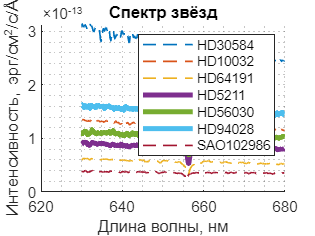

fig = figure(NextPlot= "add");
hold on;

for k = 1: amount_stars
    curve = plot(lamda, spectra(:, k));
    if speed(k) < 0
        set(curve, 'LineWidth', 1, 'LineStyle', '--') 
    else
        set(curve, 'LineWidth', 3, 'LineStyle', '-'); 
    end
end

ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
xlabel('Длина волны, нм');
title('Спектр звёзд');
grid minor;
legend(star_names);
hold off;


% saveas(fig, "plot", "png")

**Вектор movaway с именами звёзд, которые удаляются от Земли**

movaway = star_names(speed > 0);
